# 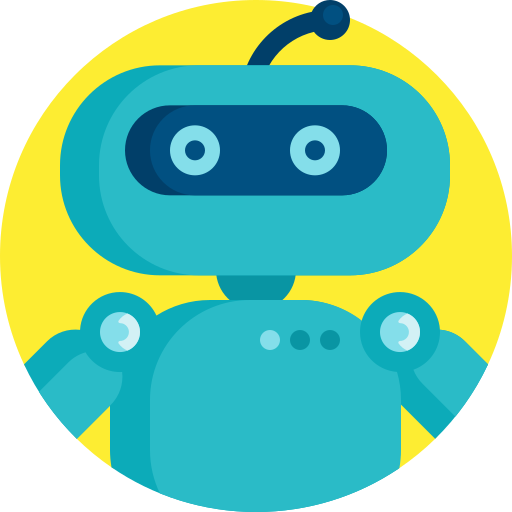

# **MEC4127F: Introduction to Robotics**

# Chapter 8: Control design for wheeled robots

## 8.1 Introduction

This Chapter will focus on introductory nonlinear control methods that relate to a differentially-steered mobile robot. Generalised concepts will also be covered that apply to any type of rigid-body platform, which will be useful in later chapters when tackling quadcopter control design. 

The motion control problem for wheeled robots often only considers the kinematic model, ignoring the underlying dynamics of the platform. In this way, the translational and angular velocities of the robot in $\{B\}$ are treated as the virtualised controller commands. The assumption here is that a low-level controller exists that commands wheel torques and can regulate the translational and angular velocities with sufficient bandwidth and precision. In other words, the wheel speed control is sufficiently fast, relative to the mobility of the wheeled robot, such that it can be assumed instantaneous.

## 8.2 Body-frame position error 

In order to incorporate feedback control on our mobile robot, we first need to define the error that will drive our control loop. In the case of position control we require a position error. Because we are assuming that we can directly control translational and angular velocity in $\{B\}$, it makes sense to define our position error in $\{B\}$ — where the control action is directly taking place. 

### 8.2.1 Position error in SE(3)

With reference to Figure 8.1, we will start by describing the current position of our robot in $\{W\}$ as


$${^W{\bf p}}={^W{\bf t}_B},$$


which describes, as before, the location of the frame $\{B\}$ origin with respect to $\{W\}$. 

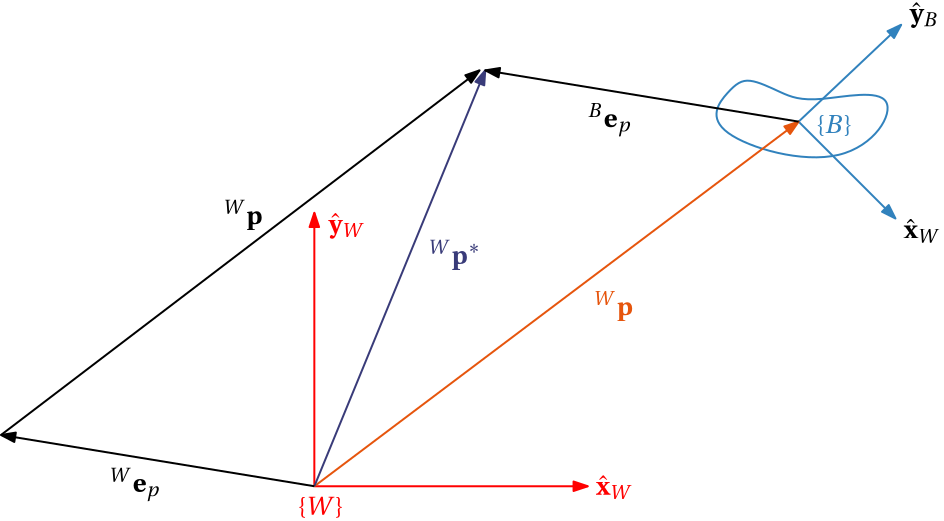

**Figure 8.1:** Representation of three key frames for control design:$\{W\}$, $\{B\}$, and $\{D\}$.

The desired reference is indicated by $\{D\}$, which describes how we ultimately want our robot to be configured. The desired position therefore follows as


$${^W{\bf p}^*}={^W{\bf t}_D}.$$


The position error in $\{W\}$ is then given by


$$\begin{array}{cc}{ ^W{\mathbf e}}_p = { ^W{\mathbf p}^\ast} - { ^W{\mathbf p}}.\end{array}$$


We unfortunately cannot directly use the error vector above for control, as the actuation of the robot as a result of the wheel speeds takes place in $\{B\}$. Instead, we will re-represent vector ${^W{\bf p}^*}={^W{\bf t}_D}$ with respect to $\{B\}$, namely, ${^B{\bf p}^*}$, which describes the incremental position change required in $\{B\}$ to move the robot to the desired position. Based on **Chapter 2**, we can determine this quantity using our generalised vector mapping equation:


$$\begin{array}{ll}
{^B{\bf p}^*}
&=&{^B{\bf R}_W}{^W{\bf p}^*}+{^B{\bf t}_W},\\
&=&{^B{\bf R}_W}{^W{\bf p}^*}-{^B{\bf R}_W}{^W{\bf t}_B},\\
&=&{^B{\bf R}_W}\left({^W{\bf p}^*}-{^W{\bf t}_B}\right),\\
&=&{^B{\bf R}_W}\left({^W{\bf p}^*}-{^W{\bf p}}\right),\\
&=&{^B{\bf R}_W}{^W{\bf e}_p},\\
&=&{^B{\bf e}_p}.
\end{array}$$


The quantity above can be thought of both as a desired position in $\{B\}$, ${^B{\bf p}^*}$, or a position error in $\{B\}$, ${^B{\bf e}_p}$, as the current position in $\{B\}$ will always be equal to zero — ${^B{\bf p}}={{\bf 0}}.$ In SE(3), ${^W{\bf R}_B}\in \text{S0}(3)$, implying that orientation representation must be chosen, with exponential coordinates and quaternions serving as popular and reliable choices.

Note that we could have also obtained the result above by mapping the world-frame position error through our rotation matrix describing $\{W\}$ with respect to $\{B\}$, namely


$$\begin{array}{cc}{ ^B{\mathbf e}}_p = {^B {\mathbf R}_W} { ^W{\mathbf e}}_p,\end{array}$$


where ${^W{\bf e}_p}\in \mathbb{R}^3$. We do not need to account for the translation between the two frame origins as we are interested in the *differential* behaviour of our system. Error signal ${ ^B{\mathbf e}}_p$ gives an indication of how the robot needs to make corrections in $\{B\}$, which is where actuation is directly acting. It is important to highlight that we cannot perform arbitrary position control if we do not know the current orientation of the robot. By extension, inaccuracies in our orientation estimate will negatively affect our position controller, by virtue of an incorrect position error.

Once we have formulated the rectilinear tracking problem in the actuator space, we can design a control scheme that minimises this error. Successfully enforcing  ${ ^B{\mathbf e}}_p \rightarrow {\mathbf 0}$ implies that  ${ ^W{\mathbf p}}={ ^W{\mathbf p}^\ast}$, which is easy to verify based on the equations above. In other words, our robot position in the task space will have reached its desired location. The type of controller used will vary depending on the particular platform, but the archetypal *PID* control structure is generally used and adapted where appropriate — we can "disable" elements of a PID controller to reduce it to a proportional controller, proportional-plus-integral controller, or proportional-derivative controller — which comes down to the specific robotic use case. 

### 8.2.2 Position error in SE(2)

When operating on a plane, such as is the case for wheeled robots, the rotation matrix is described by


$$\begin{array}{cc}{^W{\mathbf R}_B} = \left[\begin{array}{cccccccc}    \cos{\psi} & -\sin{\psi} \\    \sin{\psi} & \cos{\psi} \\ \end{array}\right]\in \text{SO}(2), \end{array}$$


where $\psi$ uniquely defines the orientation of the robot. By extension, the position error will be a two-vector made up by


$$\begin{array}{cc}{ ^B{\mathbf e}}_p = {^B {\mathbf R}_W} { ^W{\mathbf e}}_p\in \mathbb{R}^2.\end{array}$$


#### Example: Position error on a plane

The code block generates a visualisation for a wheeled robot on a plane. The position error in $\{B\}$ is also provided, based on the equation above. 

You should notice that:

- The position error in $\{W\}$ is not affected by the current orientation.

- The position error in $\{B\}$ is a function of the current orientation, but not of the orientation of $\{D\}$.

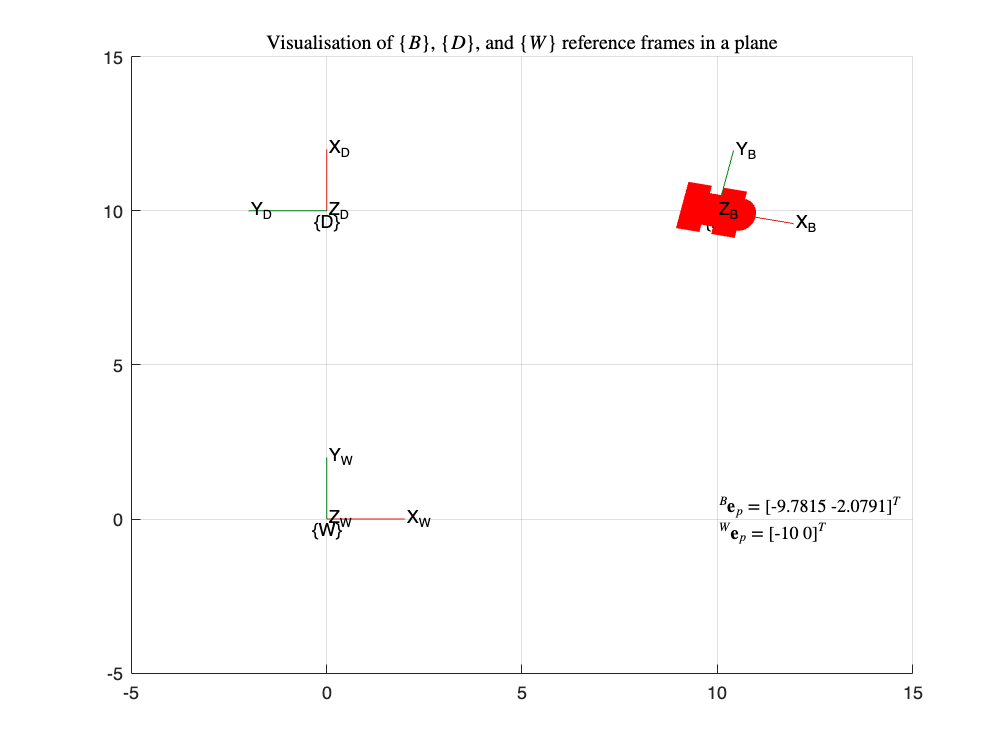

clear

psi =-12*pi/180;

figure(1),clf
%{D}
t_d2w = [0 10 0];
q_d2w = [cos(pi/4) 0 0 sin(pi/4)];
plotTransforms(t_d2w, q_d2w, "Parent", gca, "View","2D", "FrameSize", 2,"FrameAxisLabels","on","FrameLabel","D");
%{B}
t_b2w = [10 10 0];
q_b2w = [cos(psi/2) 0 0 sin(psi/2)];
plotTransforms(t_b2w, q_b2w, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", 2,"FrameAxisLabels","on","FrameLabel","B");
%{W}
plotTransforms([0 0 0], [1 0 0 0], "Parent", gca, "View","2D", "FrameSize", 2,"FrameAxisLabels","on","FrameLabel","W");
axis([-5 15 -5 15]),grid on
view(2)

R = [cos(psi) -sin(psi);
     sin(psi)  cos(psi)];
e_w = t_d2w(1:2)'-t_b2w(1:2)';
e_b = R'*e_w;

title('Visualisation of $\{B\}$, $\{D\}$, and $\{W\}$ reference frames in a plane',Interpreter="latex")
text(10,0,{['${^B{\bf e}_p}=[$',num2str(e_b(1)),'  ',num2str(e_b(2)),'$]^T$'],...
    ['${^W{\bf e}_p}=[$',num2str(e_w(1)),'  ',num2str(e_w(2)),'$]^T$']},Interpreter="latex")

## 8.3 Body-frame orientation error

Correcting the orientation of a generic platform follows a similar thinking as that of the position error, albeit with some additional intricacies. We will consider two approaches to generating a description of the body-frame orientation error:

- Rotation matrices

- Quaternions

When dealing with robotic platforms that can move outside of a fixed plane (e.g. a quadcopter), simply taking the difference between the desired and actual Euler angle vectors is not an appropriate description of the orientation error in $\{B\}$ — where the control action is going to take place. We can still try map this world-frame Euler error to the body-frame using a special matrix mapping, but the sequential nature of Euler angles is not in line with our rigid bodies are expected to behave in general. For that reason, we will consider other approaches. Note that the Euler error approach is suitable when the angle errors are sufficiently small.

### 8.3.1 Rotation matrix formulation 

This subsection will cover the generalised case of operating in SO(3), but without loss of generality, this method can always be reduced to SO(2). We start by describing the orientation of our body-frame with respect to the world-frame, using  ${^W{\mathbf R}_B}$, where our matrix is parameterised by quaternions, exponential coordinates, or some other representation. We can additionally describe a *desired* orientation using  ${^W{\mathbf R}^*_B}={^W{\mathbf R}_D}$ . With reference to Figure 8.2, this desired orientation implies that we are introducing a third reference frame that describes how we would like our body-frame to be oriented relative to $\{W\}$.

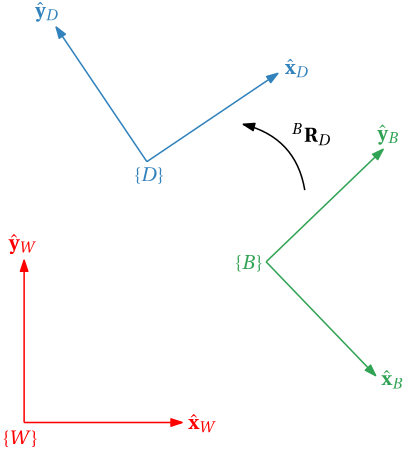

**Figure 8.2:** Depiction of the three fundamental reference frames when resolving orientation error.
 

If our desired orientation is different to our current orientation (${^W{\mathbf R}_B}\neq{^W{\mathbf R}_D}$), we will require some kind of adjustment in order to orchestrate the correct rotation, whereas if the two are aligned (${^W{\mathbf R}_B}={^W{\mathbf R}_D}$), we do not need to do anything. In general, we would like to find a desired orientation that is described in $\{B\}$, which tells us how the body frame needs to alter itself to meet our target configuration. Pre-multiplying  ${^W{\mathbf R}_D}$ by  ${^W{\mathbf R}_B^T}={^B{\mathbf R}_W}$ , we can map the desired orientation in $\{W\}$ to the desired orientation in $\{B\}$, which is given by 


$$\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D}. \end{array}$$


Note again how the sub- and superscripts cancel out to yield the resulting rotation matrix. Matrix ${^B{\mathbf R}_D}$ gives an indication of how the platform orientation, described in the body-frame, should reorient itself in order to meet the world-frame objective of  ${^W{\mathbf R}^*_B}={^W{\mathbf R}_D}$ , and also can be thought of as the encoded orientation error, as the body-frame orientation will always remain null. 

We can decode the resulting rotation matrix $\begin{array}{cc}{^B{\mathbf R}_D}  \end{array}$ to obtain a vector description of the error, which could take the form of exponential coordinates or Euler error. This 3-vector of angles can then be used to inform the robot platform of how to correct its orientation about the three axes in $\{B\}$.

#### 8.3.1.1 Euler error

Assuming the body-frame Euler errors are of interest, one can extract this information from 


$$\begin{array}{cc}^B{\mathbf R}_D = \left[\begin{array}{cccccccc}    r_{11} & r_{12} & r_{13} \\    r_{21} & r_{22} & r_{23} \\    r_{31} & r_{32} & r_{33}    \\ \end{array}\right]=    \left[\begin{array}{cccccccc}    \cos{\psi_e}\cos{\theta_e} & \cos{\psi_e}\sin{\theta_e}\sin{\phi_e}-\cos{\phi_e}\sin{\psi_e} & \sin{\psi_e}\sin{\phi_e}+\cos{\psi_e}\cos{\phi_e}\sin{\theta_e}\\    \cos{\theta_e}\sin{\psi_e} & \cos{\psi_e}\cos{\phi_e}+\sin{\psi_e}\sin{\theta_e}\sin{\phi_e} & \cos{\phi_e}\sin{\psi_e}\sin{\theta_e}-\cos{\psi_e}\sin{\phi_e} \\    -\sin{\theta_e} & \cos{\theta_e}\sin{\phi_e} & \cos{\phi_e}\cos{\theta_e}    \\ \end{array}\right]    \end{array}$$


using


$$\begin{array}{cc}\phi_e = \arctan(\frac{r_{32}}{r_{33}})\end{array},$$



$$\begin{array}{cc}\theta_e = -\arcsin{r_{31},\end{array}$$



$$\begin{array}{cc}\psi_e = \arctan(\frac{r_{21}}{r_{11}}).\end{array}$$


The nature of Euler angles is that three sequential rotations are required, so the robot would need to make corrections in three discrete rotations, instead of one single rotation. This presents issues if time or energy optimality are important to the functionality of the system. Additionally, if the system is conditionally stable, having to perform three discrete rotations may not be feasible. Having said that, one can treat the three distinct rotations as one combined rotation if the rotational angles are sufficiently small such that  ${^B{\mathbf R}_D}\approx {\mathbf I}$ . This would mean that our quantification of the body-frame correction required is not perfectly accurate, but rather approximately accurate. As previously touched on, motion control for rigid-body robots does not naturally take place in ordered sequences, but rather lends itself to instantaneous gross motions. Euler angles can still be used in control systems that make use of 3D rotations if the correct considerations are made — specifically, concerning the span of orientations that the system is expected to make use of. This makes the generalised Euler error largely unusable in a control sense (unless we intend to correct orientation errors in three disparate rotations, for example on a pan-tilt-roll camera). It would also not be possible to enforce this condition if the reference Euler angle experiences large step changes, as the Euler error would become large as a result of these steps. The Euler error formulation should therefore only be used for specific robotic platforms that experience small orientation errors (not to forget the other problem with singularities!). A fixed-wing airplane is a good example where using Euler errors is appropriate given the small angle behaviour during nominal flight conditions. This, however, would not be appropriate when speaking of fighter jets that perform aggressive and high angle-of-attack manoeuvres!

#### 8.3.1.2 Exponential coordinate error

Exponential coordinates are a natural way of expressing a rotation using the combination of a rotation vector and angle. Using our understanding of exponential coordinates, we can recover an error rotation vector from rotation matrix $\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D} \end{array}$ using


$$\alpha_e=\cos^{-1}\left(\frac{1}{2}\left(\mathrm{tr}{^B{\bf R}_D}-1\right)\right),$$



$$\lfloor ^B\hat{\bf v}_e \rfloor = \frac{1}{2\sin{\alpha_e}}\left({^B{\bf R}_D}-{^B{\bf R}_D^T}\right).$$


Note that we are assuming $\alpha_e \neq \pi$ for sake of clarity. We can then combine the axis-angle form to give the exponential coordinates *exactly *describing rotation error as

${^B{\bf e}_o}=\alpha_e^B\hat{\bf v}_e$.

This vector indicates the rotational displacement in $\{B\}$ required to align $^W{\bf R}_B$ to $^W{\bf R}_D$. Unlike the caveats of Euler error vectors, the approach above exactly describes the orientation error in $\{B\}$. This is very useful when controlling the attitude of rigid-body systems. The benefit in specifying the corrective action in the form of a scaled rotation vector is that we can theoretically adjust our orientation in one smooth rotational movement, as opposed to three disjointed rotations. Note that in stark comparison to the Euler formulation, we are also not limited to only handling small angle errors — the angular error can be arbitrarily large without issue.

### 8.3.2 Quaternion error formulation 

The quaternion structure can be used instead of a rotation matrix, which is appealing for minimising numerical operations. Recall that the unit quaternion encodes the information related to a rotation vector. That is, a single rotation about a defined axis. This is appealing from a control point of view, as we can make orientation corrections simultaneously, without having to perform sequential operations or be subject to poor angle error approximations. For sake of convenience, the verbose quaternion structure is repeated below as 


$$\begin{array}{cc}{\mathbf q} = \left[\begin{array}{cc}    q_0 \\ q_x \\ q_y \\ q_z     \\ \end{array}\right] =    \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\ \sin{\frac{\alpha}{2}} \hat{\mathbf v}     \\ \end{array}\right] =     \left[\begin{array}{cc}    \cos{\frac{\alpha}{2}} \\     \sin{\frac{\alpha}{2}} v_x \\    \sin{\frac{\alpha}{2}} v_y \\    \sin{\frac{\alpha}{2}} v_z    \\ \end{array}\right].\\ \end{array}$$


Following a similar procedure as before, our quaternion representation of our robot orientation in$\{W\}$ is ${^W{\mathbf q}_B}$ , and our desired quaternion in $\{W\}$ is ${^W{\mathbf q}_D}$ . Analogous to $\begin{array}{cc}{^B{\mathbf R}_D} = {^B{\mathbf R}_W}{^W{\mathbf R}_D} \end{array}$, our error quaternion in $\{B\}$ is given by


$$\begin{array}{cc}{^B{\mathbf q}_D} = {^B{\mathbf q}_W} \otimes {^W{\mathbf q}_D}.\end{array}$$


The equation above is beneficial based on the low number of element-wise arithmetic operations relative to multiplying two rotation matrices, but we can also now extract the exponential coordinates embedded in our quaternion formulation. Given the standard unit quaternion structure, our error quaternion can be written as


$$\begin{array}{cc}{^B{\mathbf q}_D} =    \left[\begin{array}{cc}    \cos{\frac{\alpha_e}{2}} \\ \sin{\frac{\alpha_e}{2}} {^B\hat{\bf v}_e}     \\ \end{array}\right],\end{array}$$


where $\alpha_e$ corresponds to the rotation angle required to correct the orientation of the robot, and  $^B\hat{\bf v}_e$ refers to the rotation axis. Combined, the corresponding orientation error in $\{B\}$ is given by


$${^B{\bf e}_o}=\alpha_e^B\hat{\bf v}_e,$$


 which matches the result from the previous subsection when converting rotation matrices to exponential coordinate errors. 

### 8.3.3 Orientation error in SO(2)

The approaches presented above are crucial when controlling rigid-body robots, such as aerial vehicles and satellites. While the work presented above extends to all rotations in SO(3), there will be many cases when a robot is confined to a plane, in which case a single parameter, $\psi$ is required to describe orientation. As such, when operating in SO(2), the orientation error can be simply determined by taking the difference between a desired orientation, $\psi^*$, and the current orientation, $\psi$, which yields the orientation error of 


$${^W{e}_\psi}=\psi^*-\psi.$$


The rotation axis will always be perpendicular to the plane of operation, which implies that the world-frame description of orientation will be equivalent to the body-frame counterpart.

## 8.4 Point-to-point control 

We begin by considering point-to-point control, which refers to moving a robot, initially at rest, from an initial point in the task space to a final, static point, without consideration for the final orientation. The current position is described by ${^W{\bf p}}={^W{\bf t}_B}$, whereas the desired final position is ${^W{\bf p}^*}={^W{\bf t}_D}$.

### 8.4.1 Virtual control inputs

With reference to **Chapter 6**, the forward kinematics of the differentially-steered robot are repeated below for sake of convenience: 


$$\begin{array}{ll}\left[\begin{array}{cc}    ^W\dot{t}_x \\    ^W\dot{t}_y \\    \dot{\psi}    \\ \end{array}\right] &=&     \left[\begin{array}{cccccccc}    \cos{\psi} & -\sin{\psi} & 0\\    \sin{\psi} & \cos{\psi} & 0\\    0 & 0 & 1    \\ \end{array}\right]    \left[\begin{array}{cc}   v\\    0 \\    \dot\psi    \end{array}\right],\\

&=&  \left[\begin{array}{cc}    \frac{r_W}{2}\cos\psi & \frac{r_W}{2}\cos\psi\\    \frac{r_W}{2}\sin\psi & \frac{r_W}{2}\sin\psi \\  -\frac{r_W}{d} & \frac{r_W}{d}    \end{array}\right]
\left[\begin{array}{cc}    \dot\phi_L \\ \dot\phi_R   \end{array}\right],
\end{array}$$


where $v=\frac{r}{2}\left(\dot{\phi}_L+\dot{\phi}_R\right)$ and $\dot\psi=\frac{r}{d}\left( \dot{\phi}_R-\dot{\phi}_L \right)$. The actuator space is made up of $\{\dot\phi_L,\dot\phi_R\}$, which represents the low-level control of the wheeled robot. In other words, we can in theory choose at any time what we want the two wheel speeds to be. Because we know the mapping from $\{\dot\phi_L,\dot\phi_R\}$ to $\{v,\dot\psi\}$, we can abstract and simplify the problem by treating $v$ and $\dot\psi$ as our virtual control inputs. That is, they are not the signals that directly dictate the actuator states, but they are related by a mapping that remains constant. The idea here is that we can effectively decouple the two adjoined control problems (translation and rotation) into two independent problems by posing these virtual inputs in the correct way. Using the notation from Section 8.2, the virtualised kinematic model is given by


$$\left[\begin{array}{cc}    {\dot{p}_x^*} \\ {\dot{ p}^*_y}  \\ \dot\psi \end{array}\right]=\left[\begin{array}{cc}    v\cos\psi \\ v\sin\psi \\ \dot\psi \end{array}\right],$$
 

where ${\dot{p}_x^*}={\dot{t}_x^*}$ and ${\dot{p}_y^*}={\dot{t}_y^*}$. Note that at any time we can calculate the required wheel speeds using


$$\begin{array}{ll}\left[\begin{array}{cc}    \dot\phi_L \\   \dot\phi_R \end{array}\right] &=&     \frac{1}{r_W}\left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right]    \left[\begin{array}{cc}    v \\ \dot\psi    \end{array}\right],

\end{array}$$


which we would require when implementing our eventual control scheme.

### 8.4.2 Translational control

Point-to-point control considers the problem of driving a mobile robot from an initial known position, to a desired final position. In this configuration, no inherent trajectory exists and the task is to reach the final position given the non-holonomic nature of the platform, whilst taking into account the kinematic constraints imposed by the slip-free wheel model. While methods do exist to consider the orientation of the mobile robot when it reaches its destination, we will not consider it for now. 

Consider the problem of designing a feedback control law that can drive the mobile robot from some initial 2D Cartesian point to a desired location. In this scenario, the final orientation is not specified (it can be anything). An example use-case could be an autonomous surveillance vehicle that needs to visit a set of Cartesian points and then accrue information (e.g. Visual information) over an arbitrary period of time. The arbitrary robot orientation at these waypoints would not be an issue if the robot's sensor suite was able to pan (e.g. a panoramic camera) or encompassed every direction (ring of ultrasonic sensors around robot body facing outwards). Given a world-frame position error in SE(2) of  ${ ^W{\mathbf e}}_p=[{^W{e}_x}~~{^W{e}_y}]^T$, the corresponding position error in $\{B\}$ was shown to be


$$\begin{array}{cc}{ ^B{\mathbf e}}_p = {^B {\mathbf R}_W} { ^W{\mathbf e}}_p = \left[\begin{array}{cccccccc}    \cos{\psi} &\sin{\psi} \\    -\sin{\psi} & \cos{\psi} \\     \end{array}\right] { ^W{\mathbf e}}_p. \end{array}$$


Because we can only make rectilinear corrections using forward/backward velocity parallel to the  $\hat{\mathbf x}_B$ axis, we will focus on the first element in ${ ^B{\mathbf e}}_p$, namely 


$$\begin{array}{cc}{^Be_x}=\cos{\psi}{^We_x}+\sin{\psi}{^We_y}. \end{array}$$


Our first objective is to enforce ${^Be_x} \rightarrow 0$ with an appropriate control law. This corresponds with reducing the error in the forward direction of the mobile robot to zero. An appropriate control scheme that can achieve this is a proportional controller of the form


$$\begin{array}{cc}
v^* = k_v{^Be_x} = k_v \left( \cos{\psi}{^We_x}+\sin{\psi}{^We_y} \right), \end{array}$$


where $k_v>0$. In other words, our desired linear velocity in $\{B\}$ described above will only go to zero when the corresponding error in  $\hat{\mathbf x}_B$ goes to zero. An integrator is present in our open-loop transfer function (to move from the velocity signal to the resulting position that we eventually measure and use), so we have a *type-1* system that possesses the appropriate properties to guarantee zero-error tracking at steady-state for step-like signals (assuming there are no disturbances at the plant input). 

Note that when the kinematics of the wheeled robot are exactly known and there are no wheel speed saturations, the desired and actual translational velocity will be equivalent, namely,


$$v=v^*.$$


We will consider wheel speed saturation in Section 8.4.5.

The selection of  $k_v>0$ will determine the closed-loop bandwidth, and under the aforementioned model simplifications, instability will never occur. However, if we had incorporated digital effects to our control loop, we would eventually reach a point where we cannot add more gain as a result of reaching our gain margin limit. While the kinematic model is nonlinear in nature, we can model the incremental position behaviour in $\{B\}$ using the loop transfer function of


$$P_v(s)=\frac{\Delta p(s)}{^Be_x(s)}=\frac{k_v}{s},$$


with the input to this system being translation error term ${^Be_x}$, and the output being the incremental position change in $\{B\}$. Recalling [Control Systems](https://in.mathworks.com/matlabcentral/fileexchange/160301-control-systems-university-of-cape-town), the closed-loop behaviour follows as


$$T_v(s)=\frac{1}{1+\frac{s}{k_v}},$$


which implies that the bandwidth our translational controller is directly set by $k_v$. It follows that the $2\%$ settling time is given by

$t_{\pm 2\%}\approx \frac{4}{k_v}$.

The block diagram describing the closed-loop translational control behaviour is shown Figure 8.3.

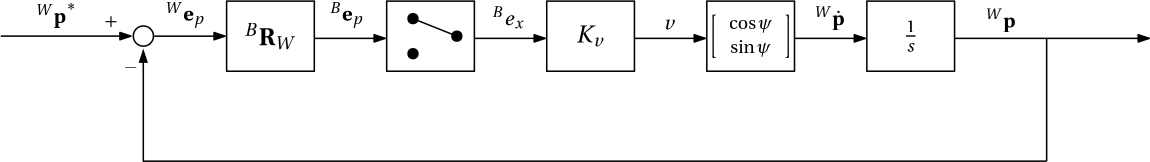

**Figure 8.3:** Block diagram of closed-loop translational control scheme.

Note that the low-level mapping of desired velocity to wheel speeds, and then to actual velocity is omitted from the block diagram above, as it is assumed that the resultant mapping is equivalent to unit gain. On a real platform this assumption cannot be made easily, as the actuators will have some non-zero time constant related to changing wheel speeds. However, we will not concern ourselves with that in this course!

#### Example: Translational control of a differentially-steered robot

The simulation resulting from the code block below demonstrates a proportional controller used to regulate the translational motion of a wheeled robot. We should notice that:

- Increasing $k_v$ decreases the settling time based on $t_{\pm 2\%}\approx \frac{4}{k_v}$;

- The robot is only able to go forwards/backwards and cannot turn;

- The error signal driving the control loop is the component of the position error parallel to $\hat{\bf x}_B$. As such, the robot will stop moving once the desired location is located on the  $\hat{\bf y}_B$-axis.

clear
d = 1; %m
r = 0.5; %m

robot = differentialDriveKinematics(WheelRadius=r,TrackWidth=d,VehicleInputs="WheelSpeeds");

dT = 0.05;
timer = rateControl(1/dT);

p_des_x =15

p_des_x = 15

k_v = 2.6;
t_st = 4/k_v;

p_des = [p_des_x 15]';
p = [];

robotPose = [5 0 pi/2]';

T = 2;
time = 0:dT:T

time =          0    0.0500    0.1000    0.1500    0.2000    0.2500    0.3000    0.3500    0.4000    0.4500    0.5000    0.5500    0.6000    0.6500    0.7000    0.7500    0.8000    0.8500    0.9000    0.9500    1.0000    1.0500    1.1000    1.1500    1.2000    1.2500    1.3000    1.3500    1.4000    1.4500    1.5000    1.5500    1.6000    1.6500    1.7000    1.7500    1.8000    1.8500    1.9000    1.9500    2.0000


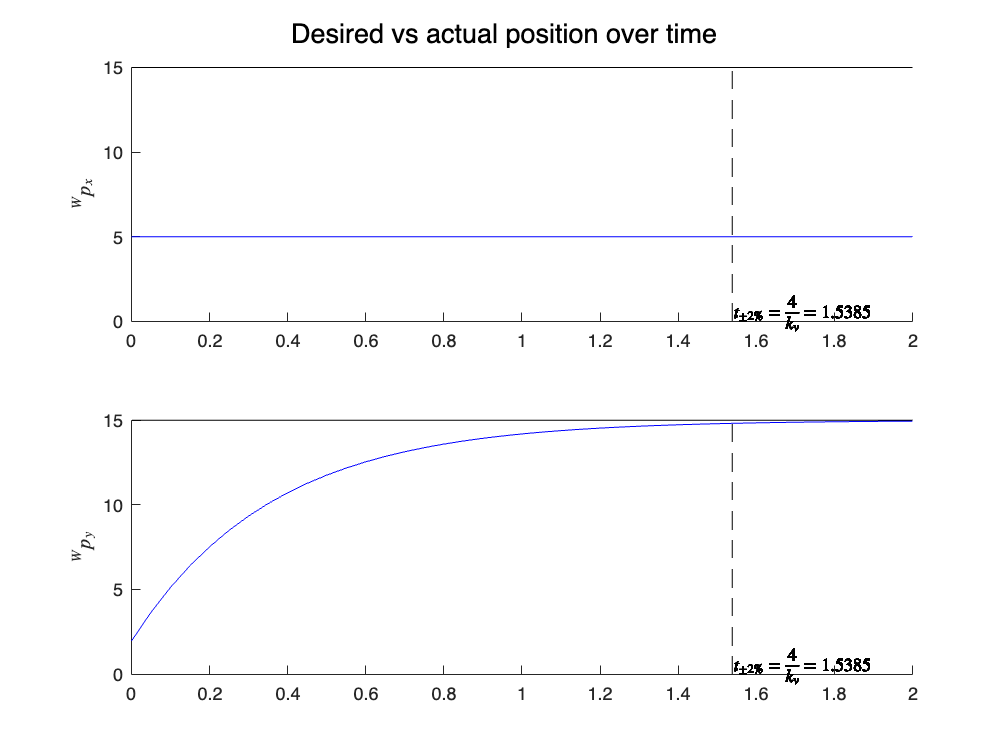

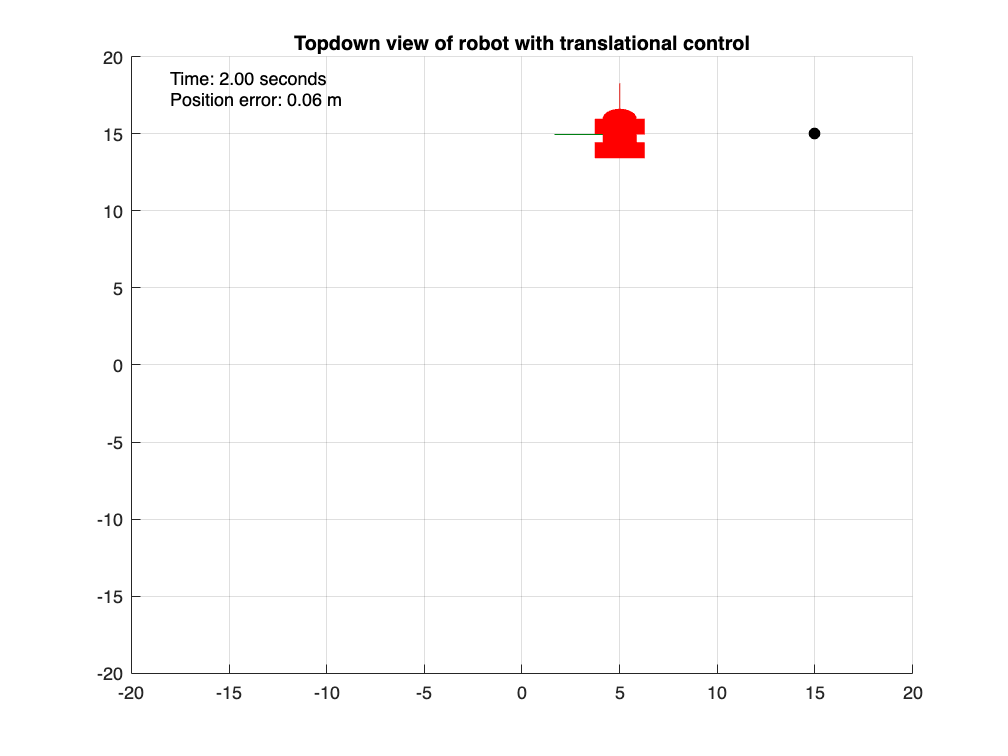

figure(2),clf
for i=1:(T/dT)+1  %run the simulation for a time equivalent to 3 seconds

    e_p_wf = p_des(1:2)-robotPose(1:2);

    psi = robotPose(3);

    e_p_bf = ( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );
    v = k_v*e_p_bf;

    A = [1 -d/2;
         1  d/2];
    phi_des = 1/r*A*[v,0]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on,title('Topdown view of robot with translational control')
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    plot(p_des(1),p_des(2),'ko',MarkerFaceColor='k')
    text(-18,18,{['Time: ',num2str( time(i),'%.2f' ), ' seconds'], ...
                 ['Position error: ',num2str( e_p_bf,'%.2f' ), ' m']})


    p = [p t(1:2)];

    figure(2),hold on,sgtitle('Desired vs actual position over time')
    subplot(2,1,1),hold on,plot(time(1:i),p(1,:),'b'),ylabel('${^Wp_x}$',Interpreter='latex')
    line([0 T],[p_des(1) p_des(1)],"color",'k')
    line([t_st t_st],[0 p_des(1)],"color",'k',"lineStyle",'--')
    text(t_st,0.5,['$t_{\pm 2\%}=\frac{4}{k_v}=$',num2str(t_st)],"Interpreter","latex")
    subplot(2,1,2),hold on,plot(time(1:i),p(2,:),'b'),ylabel('${^Wp_y}$',Interpreter='latex')
    line([0 T],[p_des(2) p_des(2)],"color",'k')
    line([t_st t_st],[0 p_des(2)],"color",'k',"lineStyle",'--') 
    text(t_st,0.5,['$t_{\pm 2\%}=\frac{4}{k_v}=$',num2str(t_st)],"Interpreter","latex")

    drawnow
    waitfor(timer);
end

### 8.4.3 Orientation control

Unlike ${^Be_x}$ , ${^Be_y}$ is uncontrollable using $v$, based on the slip-free model. We will instead resolve this error indirectly with an orientation controller. With reference to Figure 8.4, the *desired* orientation of our robot can be described using


$$\begin{array}{cc}\psi^\ast = \tan^{-1}\frac{{^We_y}}{{^We_x}}, \end{array}$$


where the four-quadrant arc-tangent function should be used in practice. In MATLAB, this is performed using the `atan2` function.

ex =0;
ey =-1;
psi_des = atan2(ey,ex)

psi_des = -1.5708

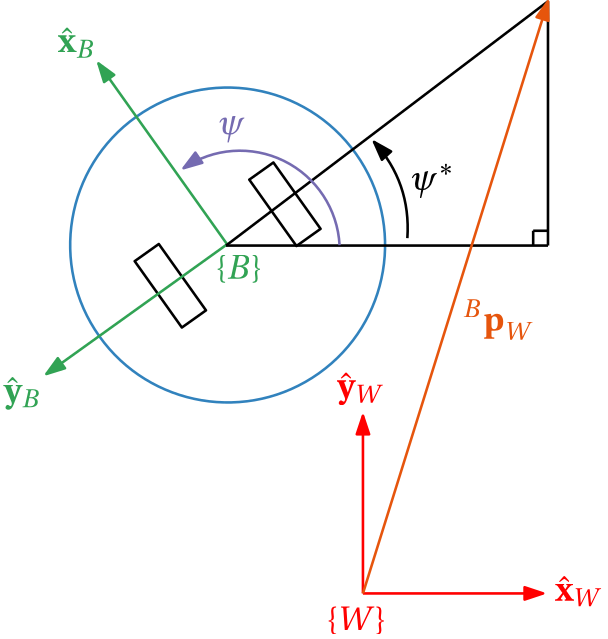

**Figure 8.4:** Resolving desired orientation from world-frame tracking error.
 

The equation above further demonstrates the coupled nature of the position and orientation in frame $\{W\}$ . The orientation follows as

$e_\psi = \psi^*-\psi$.

Given a reliable measurement/estimate of the orientation, $\psi$ , we can define a proportional control law that determines the desired rotational velocity on the robot body,


$$\begin{array}{ll} \dot\psi^* 
&=& k_\psi e_\psi,\\ 
&=& k_\psi\left( \psi^\ast-\psi \right),\\ 
&=& k_\psi \left( \tan^{-1}\frac{{^We_y}}{{^We_x}}-\psi \right), \end{array}$$


where $k_\psi>0$. As with $k_v$ , $k_\psi$ sets the bandwidth of the orientation controller, and will only be limited by digital and saturation effects when solely operating (without the translational controller). When the kinematics are perfectly known and saturation of the wheels does not occur, the desired rotational velocity is equivalent to the realised angular velocity: $\dot\psi=\dot\psi^*$.

Analogous to the translational controller, the open-loop plant representing the orientation system is modelled by


$$P_\psi(s)=\frac{\psi(s)}{e_\psi(s)}=\frac{k_\psi}{s},$$


with the input to this system being error signal $e_\psi$, and the output being $\psi$. With unit-feedback, the closed-loop behaviour follows as


$$T_\psi(s)=\frac{1}{1+\frac{s}{k_\psi}},$$


which implies that the bandwidth our translational controller is directly set by $k_\psi$. It follows that the $2\%$ settling time for the closed-loop orientation system is given by

$t_{\pm 2\%}\approx \frac{4}{k_\psi}$.

The block diagram describing the closed-loop orientation control behaviour is shown Figure 8.5.

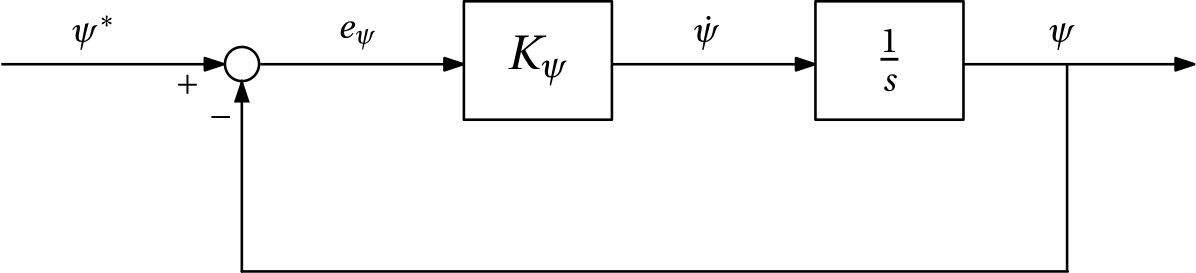

**Figure 8.5:** Block diagram of closed-loop orientation control scheme.

#### Example: Orientation control of a differentially-steered robot

The simulation resulting from the code block below demonstrates an orientation controller used to regulate the rotational motion of a wheeled robot. We should notice that:

- Increasing $k_\psi$ decreases the settling time based on $t_{\pm 2\%}\approx \frac{4}{k_\psi}$;

- The robot is only able to rotate on the spot as forward velocity is not being commanded.

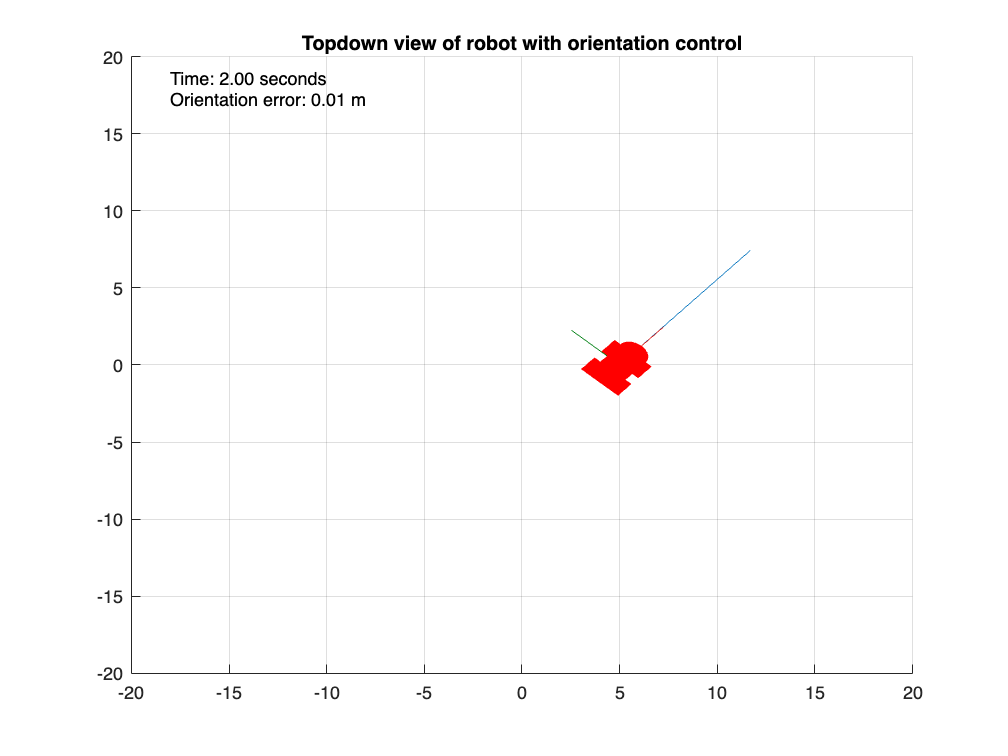

clear
d = 1; %m
r = 0.5; %m

robot = differentialDriveKinematics(WheelRadius=r,TrackWidth=d,VehicleInputs="WheelSpeeds");

dT = 0.05;
timer = rateControl(1/dT);

psi_des =48*pi/180;
k_psi = 2.3;
t_st = 4/k_psi;

psi = [];

robotPose = [5 0 0]';

T = 2;
time = 0:dT:T;
% figure(2),clf
for i=1:(T/dT)+1  %run the simulation for a time equivalent to 3 seconds

   
    e_psi = psi_des-robotPose(3);

    psi_dot = k_psi*e_psi;

    A = [1 -d/2;
         1  d/2];
    phi_des = 1/r*A*[0,psi_dot]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on,title('Topdown view of robot with orientation control')
    axis([-20 20 -20 20]),grid on
    line([robotPose(1) robotPose(1)+10*cos(psi_des)],[robotPose(2) robotPose(2)+10*sin(psi_des)])
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    % plot(psi_des(1),p_des(2),'ko',MarkerFaceColor='k')
    text(-18,18,{['Time: ',num2str( time(i),'%.2f' ), ' seconds'], ...
                 ['Orientation error: ',num2str( e_psi,'%.2f' ), ' m']})

    psi = [psi robotPose(3)];
    
    drawnow
    waitfor(timer);
end

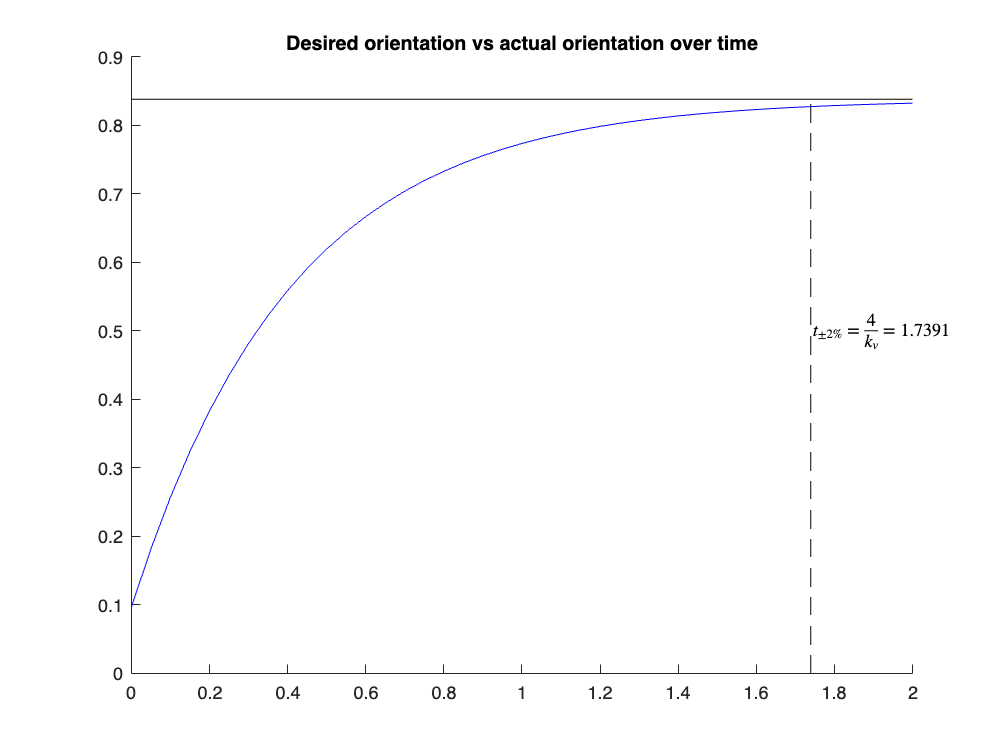


figure(2),clf,hold on,title('Desired orientation vs actual orientation over time')
plot(time,psi,'b')
line([0 T],[psi_des psi_des],"color",'k')
line([t_st t_st],[0 psi_des],"color",'k',"lineStyle",'--')
text(t_st,0.5,['$t_{\pm 2\%}=\frac{4}{k_v}=$',num2str(t_st)],"Interpreter","latex")

### 8.4.4 Combining translation and orientation control

When combined with the translation controller, the task of the orientation control scheme above is to point the robot in the direction of the desired location so that the translational controller moves the robot closer to the target location. It makes physical sense to *prioritise* this control loop over the translational controller, as the robot can incur increasingly large errors if the robot is pointing in the wrong direction at the beginning of the manoeuvre. Prioritisation is achieved by setting the bandwidth of the orientation controller to be sufficiently large relative to the bandwidth of the translational controller. A rough rule of thumb is that the bandwidth of the orientation controller should be at least twice that of the translation controller, which necessitates that


$$k_\psi>2k_v.$$


The block diagram of the full control scheme is shown in Figure 8.6.

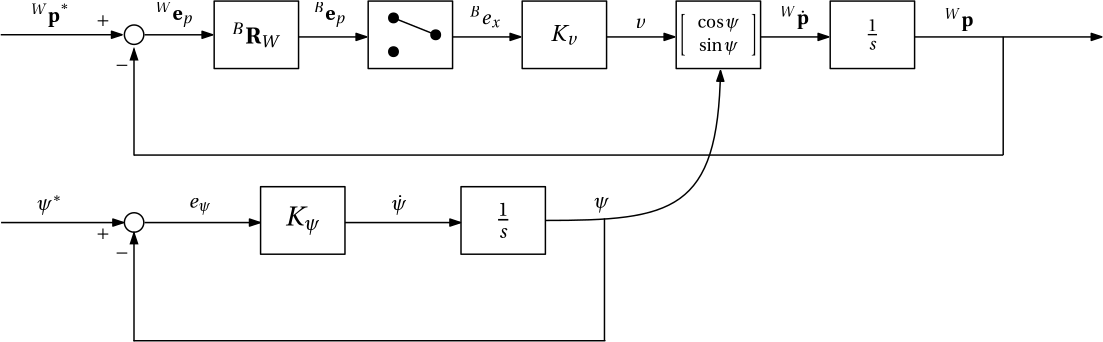

**Figure 8.6:** Block diagram of closed-loop translation and orientation control scheme.

#### Example: Pose control of a differentially-steered robot

The simulation resulting from the code block below demonstrates the combination of a translational and orientation controller used to regulate the point to point motion of a wheeled robot. We should notice that:

- Increasing $k_\psi$ decreases the rotational settling time based on $t_{\pm 2\%}\approx \frac{4}{k_\psi}$ — in other words, how quickly the robot points in the correct direction,

- Increasing $k_v$ decreases the translational settling time based on $t_{\pm 2\%}\approx \frac{4}{k_v}$ — in other words, how quickly the robot translates until such time that the error in $\hat{\bf x}_B$-axis is zero,

- The robot is able to translate and rotate simultaneously but still possesses a kinematic constraint.

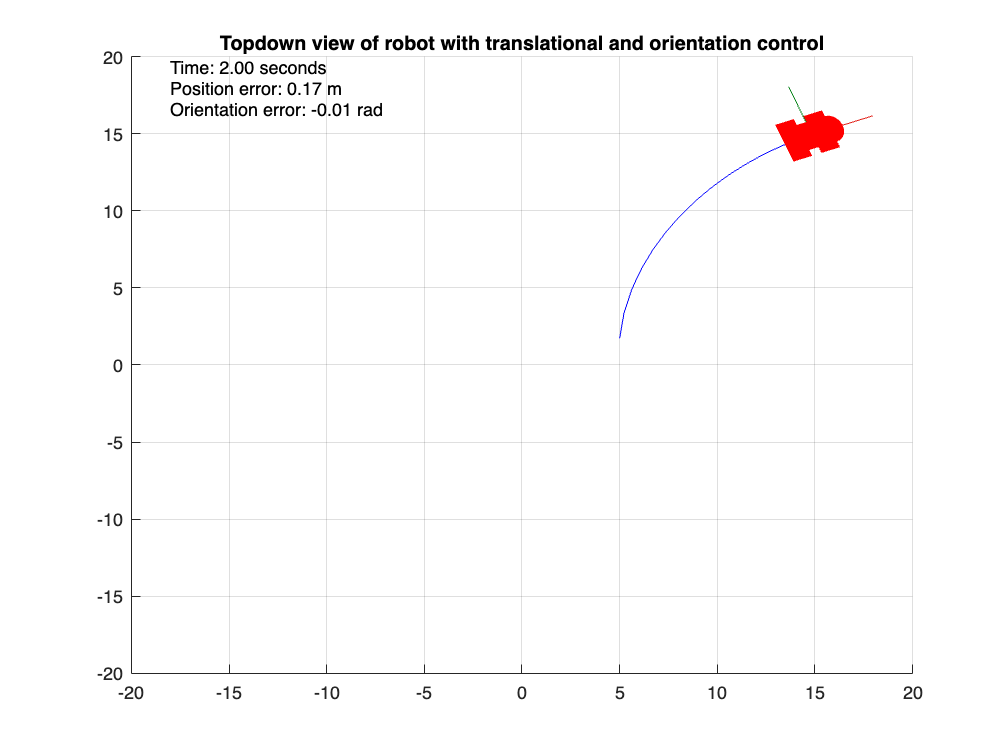

clear
d = 1; %m
r = 0.5; %m

robot = differentialDriveKinematics(WheelRadius=r,TrackWidth=d,VehicleInputs="WheelSpeeds");

dT = 0.05;
timer = rateControl(1/dT);

p_des_x =15;
k_v = 2.3;
k_psi = 4.6;

p_des = [p_des_x 15]';
p = [];

robotPose = [5 0 pi/2]';

T = 2;
time = 0:dT:T;
figure(2),clf
for i=1:(T/dT)+1  %run the simulation for a time equivalent to 3 seconds

    psi = robotPose(3);

    %translation controller
    e_p_wf = p_des(1:2)-robotPose(1:2);
    e_p_bf = ( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );
    v = k_v*e_p_bf;

    %orientation controller
    psi_des = atan2(e_p_wf(2),e_p_wf(1));
    e_psi = psi_des-psi;
    psi_dot = k_psi*e_psi;

    A = [1 -d/2;
         1  d/2];
    phi_des = 1/r*A*[v,psi_dot]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on,title('Topdown view of robot with translational and orientation control')
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    plot(p_des(1),p_des(2),'ko',MarkerFaceColor='k')
    text(-18,18,{['Time: ',num2str( time(i),'%.2f' ), ' seconds'], ...
                 ['Position error: ',num2str( e_p_bf,'%.2f' ), ' m'], ...
                 ['Orientation error: ',num2str( e_psi,'%.2f' ), ' rad']})

    p = [p t(1:2)];
    plot(p(1,:),p(2,:),'b')

    drawnow
    waitfor(timer);
end

### 8.4.5 Wheel speed limits

In practice, we also need to keep in mind that a realistic robot will have a limit to the achievable forward and rotational velocity. Specifically, in practice we have the constraints of  


$$|v|\leq {v}_{lim}, \qquad |\dot\psi|\leq {\dot\psi}_{lim}$$


where $v_{lim}$ and $\dot\psi_{lim}$ represent the respective maximum translational and rotational velocity that can be obtained by the mobile robot. Note that these limits will actually vary depending on the current wheel speed combination, as shown below. While saturation is not deeply problematic when only considering translational control or orientation control separately, saturation when controlling both translation and orientation simultaneously can result in undesirable behaviour. 

#### Example: Attempting pose control while in saturation

This code block provides a simulation of the differentially-steered robot moving to a target point using both a translational and orientation controller. Wheel speed limits are set using the slider below. You should notice that:

- when the wheel speed limit is sufficiently high, the robot behaves as expected and matches the simulation above.

- when the wheel speed limit is sufficiently low, the wheel speeds saturate, and the robot becomes "locked up" in a straight motion or turning motion (depending on which controller caused the saturation).

- the desired wheel speeds are also plotted and show that the robot behaves erratically when in saturation.

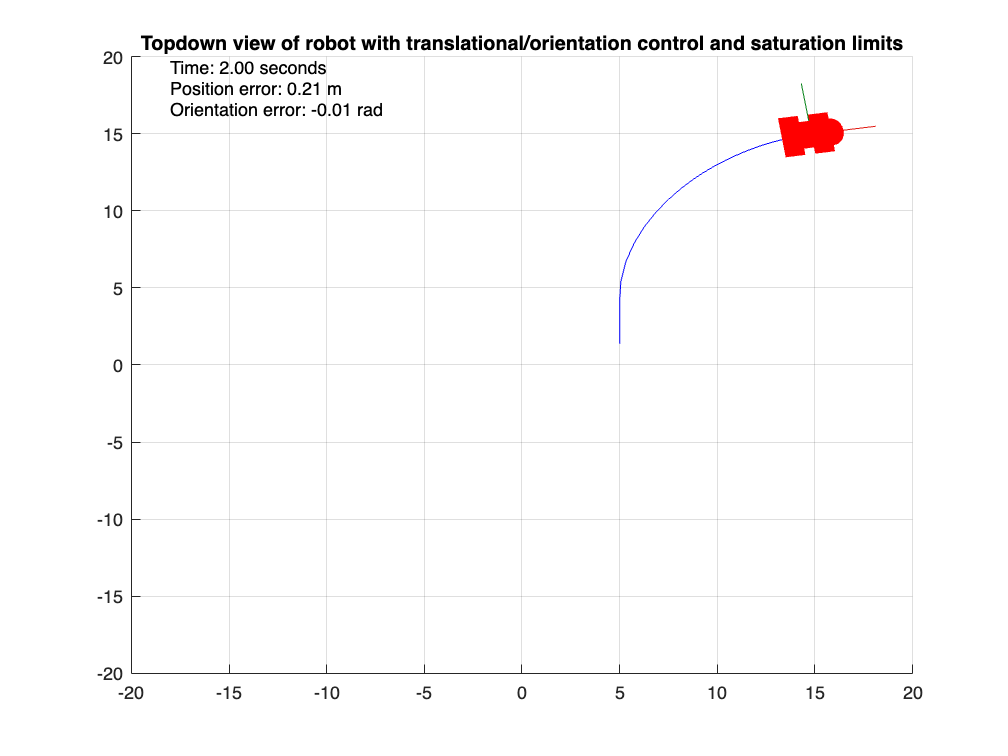

clear
d = 1; %m
r = 0.5; %m

phi_lim =55;

robot = differentialDriveKinematics(WheelRadius=r,...
        TrackWidth=d,VehicleInputs="WheelSpeeds", WheelSpeedRange=[-phi_lim phi_lim]);

dT = 0.05;
timer = rateControl(1/dT);

p_des_x = 15;
k_v = 2.3;
k_psi = 4.6;

p_des = [p_des_x 15]';
p = [];

robotPose = [5 0 pi/2]';

phi_vec = [];

T = 2;
time = 0:dT:T;
for i=1:(T/dT)+1  %run the simulation for a time equivalent to 3 seconds

    psi = robotPose(3);

    %translation controller
    e_p_wf = p_des(1:2)-robotPose(1:2);
    e_p_bf = ( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );
    v = k_v*e_p_bf;

    %orientation controller
    psi_des = atan2(e_p_wf(2),e_p_wf(1));
    e_psi = psi_des-psi;
    psi_dot = k_psi*e_psi;

    A = [1 -d/2;
         1  d/2];
    phi_des = 1/r*A*[v,psi_dot]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on,title('Topdown view of robot with translational/orientation control and saturation limits')
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    plot(p_des(1),p_des(2),'ko',MarkerFaceColor='k')
    text(-18,18,{['Time: ',num2str( time(i),'%.2f' ), ' seconds'], ...
                 ['Position error: ',num2str( e_p_bf,'%.2f' ), ' m'], ...
                 ['Orientation error: ',num2str( e_psi,'%.2f' ), ' rad']})

    p = [p t(1:2)];
    plot(p(1,:),p(2,:),'b')

    phi_vec = [phi_vec [phiL,phiR]'];

    drawnow
    waitfor(timer);
end

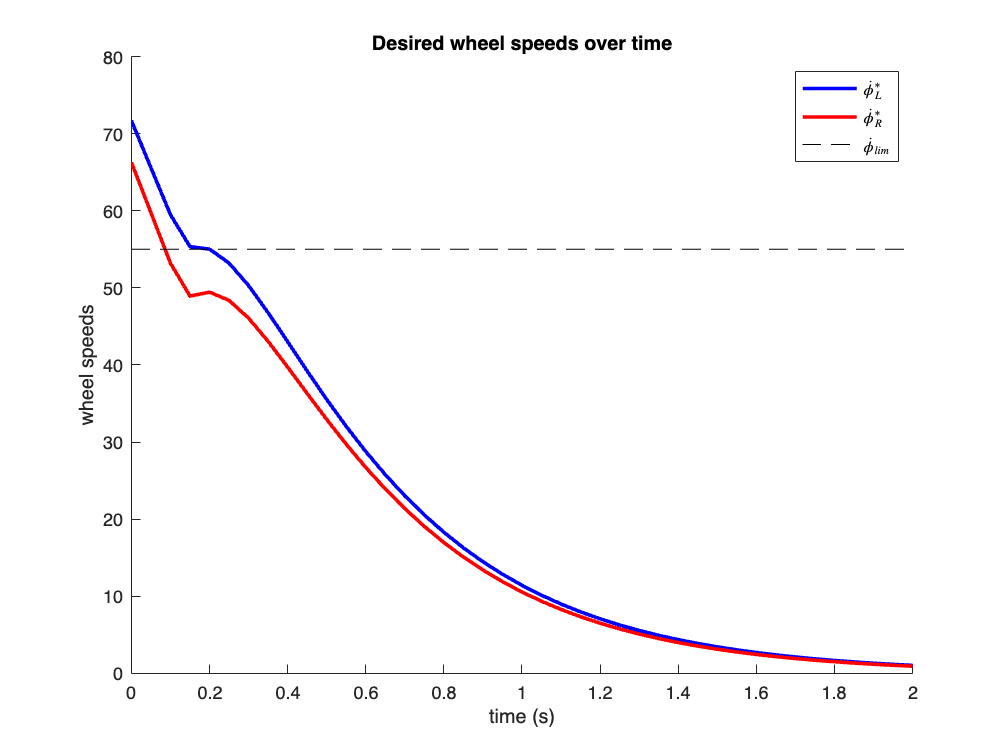


figure(2),clf,hold on,title('Desired wheel speeds over time')
plot(0:dT:T,phi_vec(1,:),'b',LineWidth=2)
plot(0:dT:T,phi_vec(2,:),'r',LineWidth=2)
line([0 T],[phi_lim phi_lim],'color','k','lineStyle','--')
legend('$\dot\phi_L^*$','$\dot\phi_R^*$','$\dot\phi_{lim}$',"interpreter","latex")
xlabel('time (s)'),ylabel('wheel speeds')

The time-varying body velocity constraints originate from the fact that each wheel's velocity has a fundamental limit, namely,


$$\left| \dot\phi_L\right|\leq \dot\phi_{lim}, \qquad \left| \dot\phi_R\right|\leq \dot\phi_{lim}.$$


Recall that


$$v=\frac{r_W}{2}\left(\dot\phi_L+\dot\phi_R\right), \qquad \dot\psi=\frac{r_W}{d}\left(\dot\phi_R-\dot\phi_L\right).$$


If, for example, both wheel speeds are at their positive maximum, which is given by $\dot\phi_L=\dot\phi_R=\dot\phi_{lim}$, then this implies that


$$v={r_W}\dot\phi_{lim}, \qquad \dot\psi=0.$$


The result above suggests that the robot can translate at a high speed but has no available control action to adjust orientation. Conversely, if $\dot\phi_L=-\dot\phi_R=\dot\phi_{lim}$, then this implies that


$$v=0, \qquad \dot\psi=\frac{2r_W}{d}\dot\phi_{lim}.$$


This suggests that when the wheel speeds are at their maximum but opposite in polarity, no translational control action is available, whereas orientation control is still possible. The two results above imply that when there are wheel velocity limits imposed on the wheeled robot, the orientation and translation controller must share the finite control action available. 

Consulting the mapping below of


$$\begin{array}{ll}\left[\begin{array}{cc}    v \\    \dot\psi \end{array}\right] 
&=& r_W\left[\begin{array}{cc}    \frac{1}{2} & \frac{1}{2}\\    -\frac{1}{d} & \frac{1}{d}\end{array}\right]
\left[\begin{array}{cc}    \dot\phi_L \\ \dot\phi_R    \end{array}\right],\\
\end{array}$$


one can plot the relationship between all admissible wheel speeds that adhere to $\{\left| \dot\phi_L\right|,\left| \dot\phi_R\right|\}\leq \dot\phi_{lim}$, as well as the resulting body velocities, which is given in Figure 8.7.

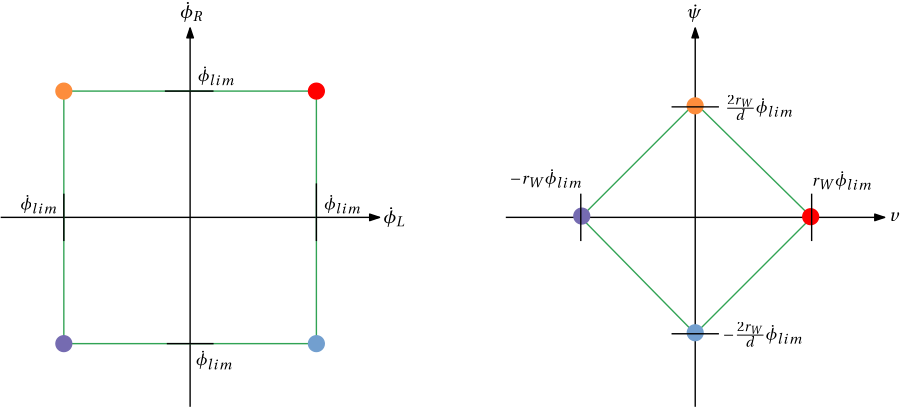

**Figure 8.7:** Mapping from admissible wheel speeds to body velocities. The multi-coloured points indicate correspondence between wheel velocities and resulting robot body velocities.

We therefore cannot expect the robot to translate at its maximum velocity and simultaneously rotate at the maximum amount. Instead, there will need to be a balance at all times between the rotational and translational velocity of the robot. The right-hand side figure above implies that $\dot\psi$ has four constraints in order to adhere to its admissible solution space:


$$\dot\psi \leq -\frac{b}{a}v+b, \qquad \dot\psi \geq -\frac{b}{a}v-b, \qquad \dot\psi \leq \frac{b}{a}v+b, \qquad \dot\psi \geq \frac{b}{a}v-b,$$


where $b=\frac{2r_W}{d}\dot\phi_{lim}$ is the y-intercept of the body velocity space (where maximum angular velocity is obtainable), and $a=r_W\dot\phi_{lim}$ is the x-intercept (maximum forward velocity is obtainable).

#### Example: Mapping of wheel speeds to body velocities

This example shows the mapping from chosen wheel speeds to the corresponding body velocities. The fixed boundary of the two workspaces is also indicated.

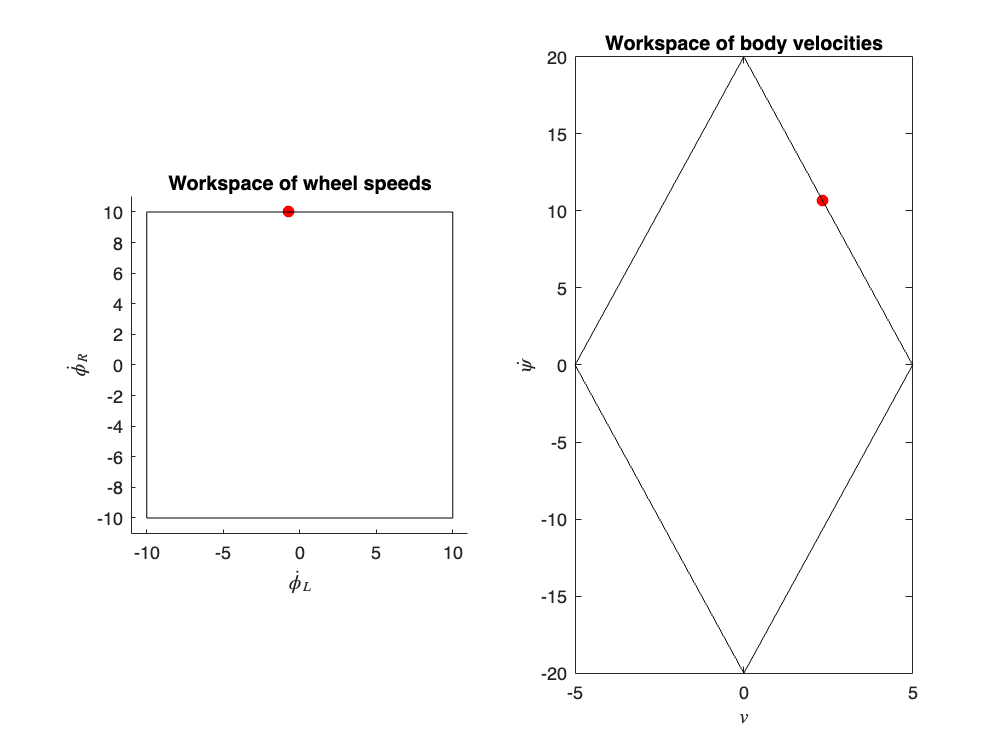

phiL =-0.7;
phiR =10;

phi_lim = 10;
d = 0.5;
rw = 0.5;
A = rw*[0.5 0.5; -1/d 1/d];
body_vel = A*[phiL phiR]';

a = rw*phi_lim;
b = 2*rw/d*phi_lim;

figure(1),clf
subplot(1,2,1),hold on,title('Workspace of wheel speeds')
plot(phiL,phiR,'ro',MarkerFaceColor='r')
line([-phi_lim phi_lim],[phi_lim phi_lim],"color",'k')
line([-phi_lim phi_lim],-[phi_lim phi_lim],"color",'k')
line([phi_lim phi_lim],[-phi_lim phi_lim],"color",'k')
line(-[phi_lim phi_lim],[-phi_lim phi_lim],"color",'k')
axis equal,xlim([-11 11]),ylim([-11 11]),xlabel('$\dot\phi_L$','interpreter','latex'),ylabel('$\dot\phi_R$','interpreter','latex')
subplot(1,2,2)
plot(body_vel(1),body_vel(2),'ro',MarkerFaceColor='r')
line([0 a],[b 0],"color",'k')
line([a 0],[0 -b],"color",'k')
line([0 -a],[-b 0],"color",'k')
line([-a 0],[0 b],"color",'k')
xlabel('$v$','interpreter','latex'),ylabel('$\dot\psi$','interpreter','latex'),title('Workspace of body velocities')

Recalling the inverse mapping, the desired wheel speeds are determined from the body velocities using


$$\begin{array}{ll}\left[\begin{array}{cc}    \dot\phi_L^* \\   \dot\phi_R^* \end{array}\right] &=&     \frac{1}{r_W}\left[\begin{array}{cccccccc}    1 & -\frac{d}{2}\\    1 & \frac{d}{2} \end{array}\right]    \left[\begin{array}{cc}    v \\ \dot\psi    \end{array}\right].\\

\end{array}$$


If a combination of $\{v,\dot\psi\}$ is specified that will exceed the wheel speed constraints of $\{\left| \dot\phi_L\right|,\left| \dot\phi_R\right|\}\leq \dot\phi_{lim}$, then our robot will hit a saturation and not behave as expected. Put differently, we require our wheel speeds to lie within the boundaries described by Figure 8.7 — body velocities that request wheel speeds outside of the wheel speed workspace cannot be achieved. This is described aptly by the equations below for each wheel:

$\dot\phi_L =\left\{
        \begin{array}{ll}
          \dot\phi_L^*, &  |\dot\phi_L^*|\leq \dot\phi_{lim}, \\
           \dot\phi_{lim}, & \dot\phi_L^*>\dot\phi_{lim}, \\
           -\dot\phi_{lim}, & \dot\phi_L^*<-\dot\phi_{lim}. \\
        \end{array}
    \right.$,          $\dot\phi_R =\left\{
        \begin{array}{ll}
          \dot\phi_R^*, &  |\dot\phi_R^*|\leq \dot\phi_{lim}, \\
           \dot\phi_{lim}, & \dot\phi_R^*>\dot\phi_{lim}, \\
           -\dot\phi_{lim}, & \dot\phi_R^*<-\dot\phi_{lim}. \\
        \end{array}
    \right.$

Given the coupled nature of trying to simultaneously orient the robot and move towards a target location, saturation can cause the robot to shoot off in the entirely wrong direction and possibly never recover. For this reason, we aim to avoid saturation at all times. The easiest approach is to choose sufficiently small gains so that large control actions are never commanded. However, this may result in response times that are too slow for the particular task at hand.

One could instead share the control action between the orientation and translation controller based on the maximum allowable wheel speeds. Recalling that satisfying


$$\dot\psi \leq -\frac{b}{a}v+b, \qquad \dot\psi \geq -\frac{b}{a}v-b, \qquad \dot\psi \leq \frac{b}{a}v+b, \qquad \dot\psi \geq \frac{b}{a}v-b,$$


is required for a valid body velocity vector, we can first determine the required $\dot\psi$ based on the demands of the orientation controller, as shown in Section 8.4.3, and then subsequently determine the largest velocity value that satisfies the constraints above. This value can then be used as a velocity limit on the translational controller so that saturation never occurs. This velocity limit is given by


$$v_{lim} =
a-\frac{a}{b}\dot\psi.$$


#### Example: Determining the velocity limit given a required angular velocity

This example shows how the velocity limit can be obtained by solving the equation above when an angular velocity is specified. You should notice that:

- The wheel speeds and body velocities will always sit on the boundary of the respective workspaces, based on determining $v_{lim}$ using the equation above.

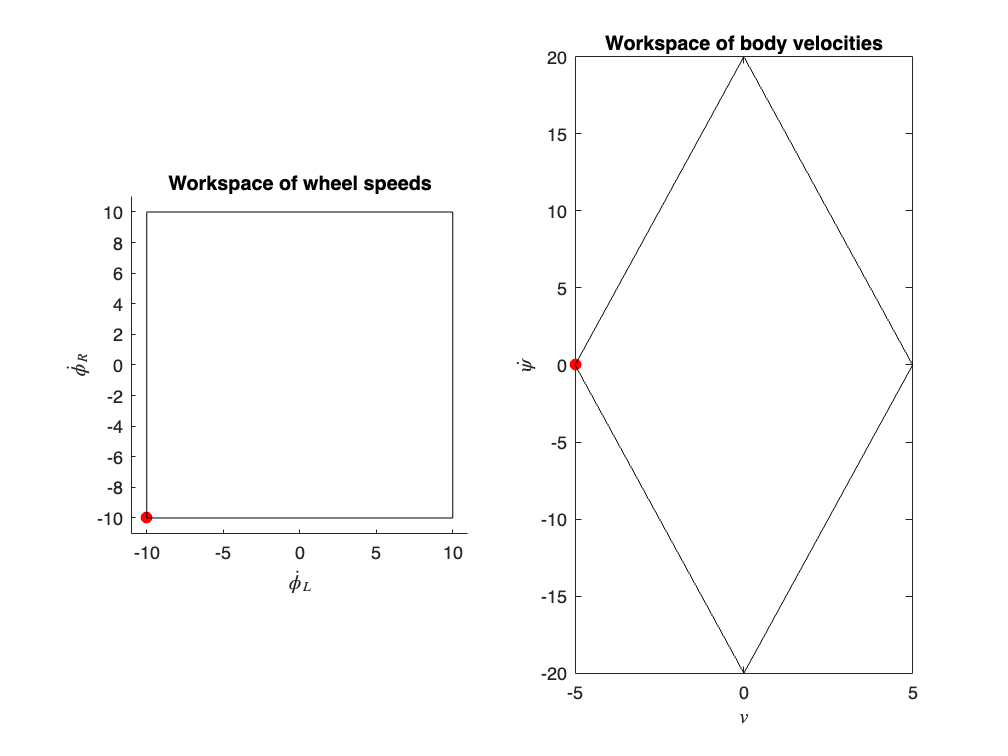

psi_dot =0;
vel_direction =-1;

phi_lim = 10;
d = 0.5;
rw = 0.5;
A = rw*[0.5 0.5; -1/d 1/d];

a = rw*phi_lim;
b = 2*rw/d*phi_lim;

v = vel_direction*( a-a/b*abs(psi_dot) );

body_vel = [v,psi_dot]';
wheel_speeds = A\body_vel;

figure(1),clf
subplot(1,2,1),hold on
plot(wheel_speeds(1),wheel_speeds(2),'ro',MarkerFaceColor='r')
line([-phi_lim phi_lim],[phi_lim phi_lim],"color",'k')
line([-phi_lim phi_lim],-[phi_lim phi_lim],"color",'k')
line([phi_lim phi_lim],[-phi_lim phi_lim],"color",'k')
line(-[phi_lim phi_lim],[-phi_lim phi_lim],"color",'k')
axis equal,xlim([-11 11]),ylim([-11 11])
title('Workspace of wheel speeds')
xlabel('$\dot\phi_L$','interpreter','latex'),ylabel('$\dot\phi_R$','interpreter','latex')
subplot(1,2,2),plot(body_vel(1),body_vel(2),'ro',MarkerFaceColor='r')
line([0 a],[b 0],"color",'k')
line([a 0],[0 -b],"color",'k')
line([0 -a],[-b 0],"color",'k')
line([-a 0],[0 b],"color",'k')
% xlim([-10 10]),ylim([-20 20])
xlabel('$v$','interpreter','latex'),ylabel('$\dot\psi$','interpreter','latex'),title('Workspace of body velocities')

We can include the saturation detection scheme in our previous code block that attempted to perform pose control under saturation. Given that the velocity limit is described by


$$v_{lim} =
a-\frac{a}{b}\dot\psi,$$


the velocity command will be determined by


$$v =\left\{
        \begin{array}{ll}
          v^*, &  |v|\leq v_{lim}, \\
           v_{lim}, & v^*>v_{lim}, \\
           -v_{lim}, & v^*<-v_{lim},
        \end{array}
    \right.$$


where $v^*=k_v{^Be_x}$ is the commanded velocity dictated by the translational controller.

#### Example: Attempting pose control when using saturation detection

This code block provides a simulation of the differentially-steered robot moving to a target point using both a translational and orientation controller. Wheel speed limits are set using the slider below and a saturation detector is added to the forward velocity signal. You should notice that

- regardless of the wheel speed limit, the robot does not behave erratically,

- the demanded wheel speeds never exceed the wheel speed limits,

- saturation limits can result in increased settling times, as a result of the robot not traversing or rotating as fast as required.

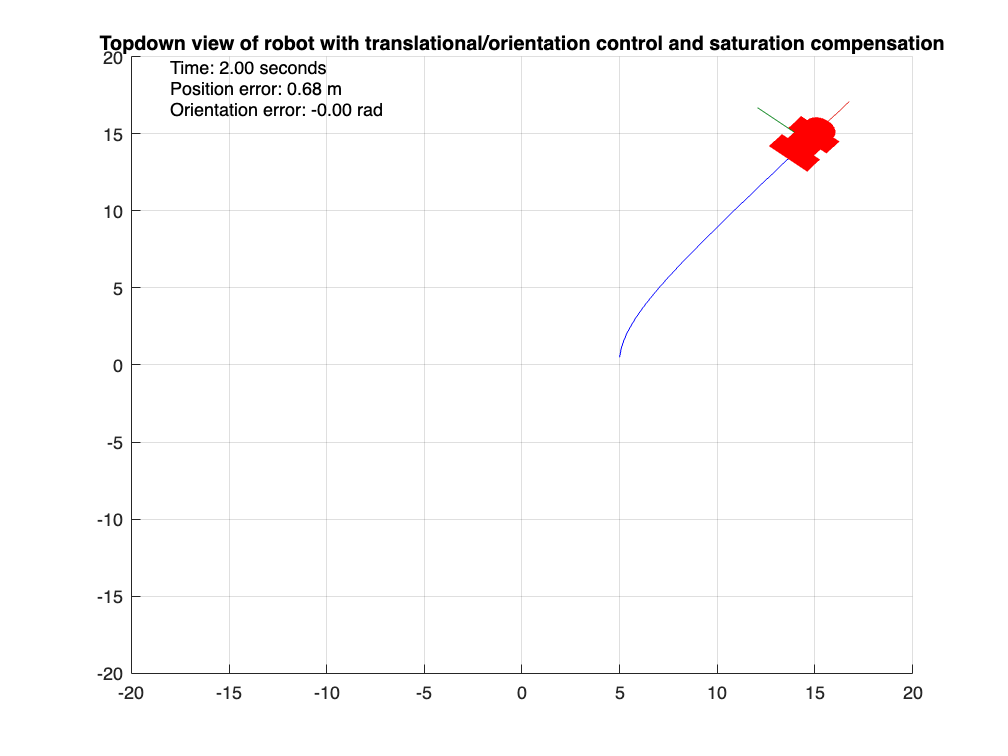

clear
d = 1; %m
r = 0.5; %m

phi_lim =23;

robot = differentialDriveKinematics(WheelRadius=r,...
        TrackWidth=d,VehicleInputs="WheelSpeeds", WheelSpeedRange=[-phi_lim phi_lim]);

dT = 0.05;
timer = rateControl(1/dT);

p_des_x = 15;
k_v = 2.3;
k_psi = 4.6;

p_des = [p_des_x 15]';
p = [];

robotPose = [5 0 pi/2]';

phi_vec = [];

a = r*phi_lim;
b = 2*r/d*phi_lim;

T = 2;
time = 0:dT:T;
for i=1:(T/dT)+1  %run the simulation for a time equivalent to 3 seconds

    psi = robotPose(3);

    %translation controller
    e_p_wf = p_des(1:2)-robotPose(1:2);
    e_p_bf = ( cos(psi)*e_p_wf(1)+sin(psi)*e_p_wf(2) );
    v = k_v*e_p_bf;

    %orientation controller
    psi_des = atan2(e_p_wf(2),e_p_wf(1));
    e_psi = psi_des-psi;
    psi_dot = k_psi*e_psi;

    %saturation detector
    v_lim = a-a/b*abs(psi_dot);
    if( abs(v) > v_lim )
        v = sign(v)*v_lim;
    end
    

    A = [1 -d/2;
         1  d/2];
    phi_des = 1/r*A*[v,psi_dot]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;

    t = [robotPose(1:2); 0];    %extract 2D position of robot
    q = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    figure(1),clf,hold on,title('Topdown view of robot with translational/orientation control and saturation compensation')
    axis([-20 20 -20 20]),grid on
    plotTransforms(t', q, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);
    plot(p_des(1),p_des(2),'ko',MarkerFaceColor='k')
    text(-18,18,{['Time: ',num2str( time(i),'%.2f' ), ' seconds'], ...
                 ['Position error: ',num2str( e_p_bf,'%.2f' ), ' m'], ...
                 ['Orientation error: ',num2str( e_psi,'%.2f' ), ' rad']})

    p = [p t(1:2)];
    plot(p(1,:),p(2,:),'b')

    phi_vec = [phi_vec [phiL,phiR]'];

    drawnow
    waitfor(timer);
end

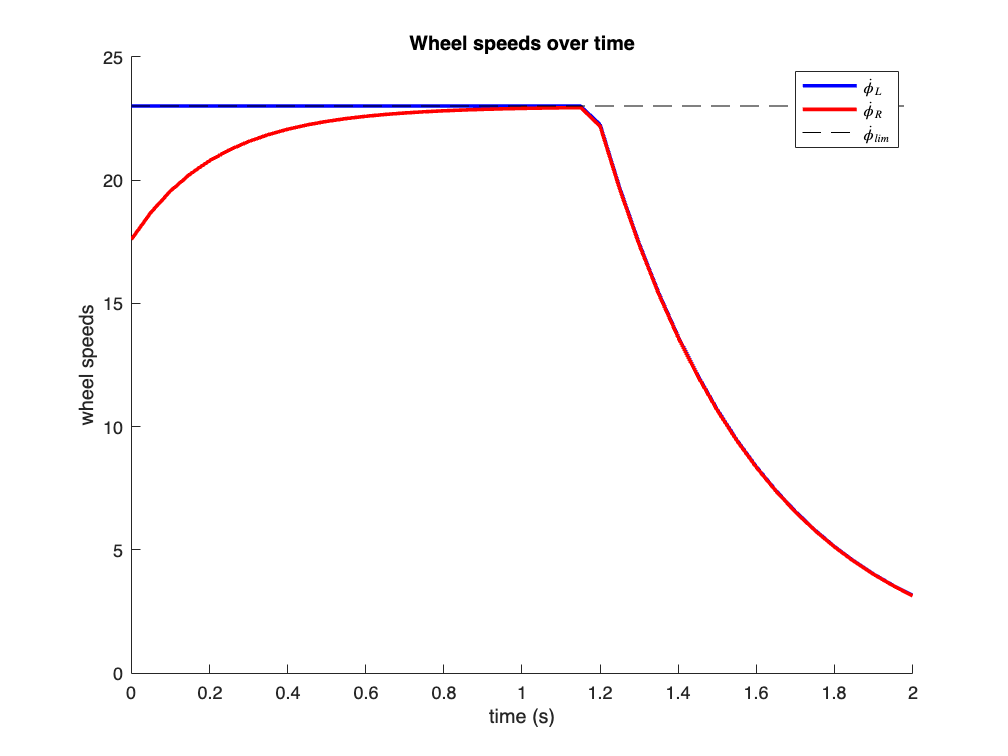


figure(2),clf,hold on,title('Wheel speeds over time')
plot(0:dT:T,phi_vec(1,:),'b',LineWidth=2)
plot(0:dT:T,phi_vec(2,:),'r',LineWidth=2)
line([0 T],[phi_lim phi_lim],'color','k','lineStyle','--')
legend('$\dot\phi_L$','$\dot\phi_R$','$\dot\phi_{lim}$',"interpreter","latex")
xlabel('time (s)'),ylabel('wheel speeds')

### 8.4.6 Norm-based translational control

The position controller in Section 8.4.2 notably only considers errors in $\hat{\mathbf x}_B$, which inherently relies on the orientation controller pointing $\hat{\mathbf x}_B$ in the direction of the target point in order for motion to proceed. In this configuration, the mobile robot will stop translating when $\hat{\mathbf y}_B$ points at the target location, and will only recommence motion once the orientation is adjusted. This can result in conservative and disjointed motion depending on the controller gains selected and initial configuration of the robot. A more aggressive method to maintain continuous velocity is to rather use the Euclidean distance from the robot to the destination as an error signal:


$$\begin{array}{cc}e_d = \sqrt{{^We_x^2}+{^We_y^2}}. \end{array}$$


The corresponding position translational control law follows as 


$$\begin{array}{cc}v = k_v{e_d} = k_v \sqrt{{^We_x^2}+{^We_y^2}}. \end{array}$$


In this form, the mobile robot will continue to translate until such time that the distance to the target location reaches zero. While this can result in a more natural and fluid motion from the start to end points, there is the risk of never reaching the target location if the proportional gain of the position controller is set too aggressively relative to the orientation controller. The control law above is also applicable to mobile robots that have a car-like or bicycle model, where changing orientation is only possible when the robot is also experiencing a linear velocity.

## 8.5 Pure pursuit trajectory tracking 

We can extend our concept of point-to-point motion to the generalised case of following a trajectory. This trajectory can originate from a trajectory generation routine (see **Chapter 7**), or from real-time information based on the robot's sensors. The basic concept of a **pure pursuit** controller is to track a reference point on the trajectory that constantly moves in relation to the robot at an approximately constant velocity. This can be likened to a donkey chasing after a carrot. With reference to Figure 8.8, our formulation of the tracking error follows on from Section 8.4.6, namely,


$$\begin{array}{cc}e_d = \sqrt{{^We_x^2}+{^We_y^2}} - d^\ast, \end{array}$$


with the inclusion of a specified following distance, $d^\ast$, which corresponds with the desired displacement between the robot (donkey) and pursuit point (carrot). 

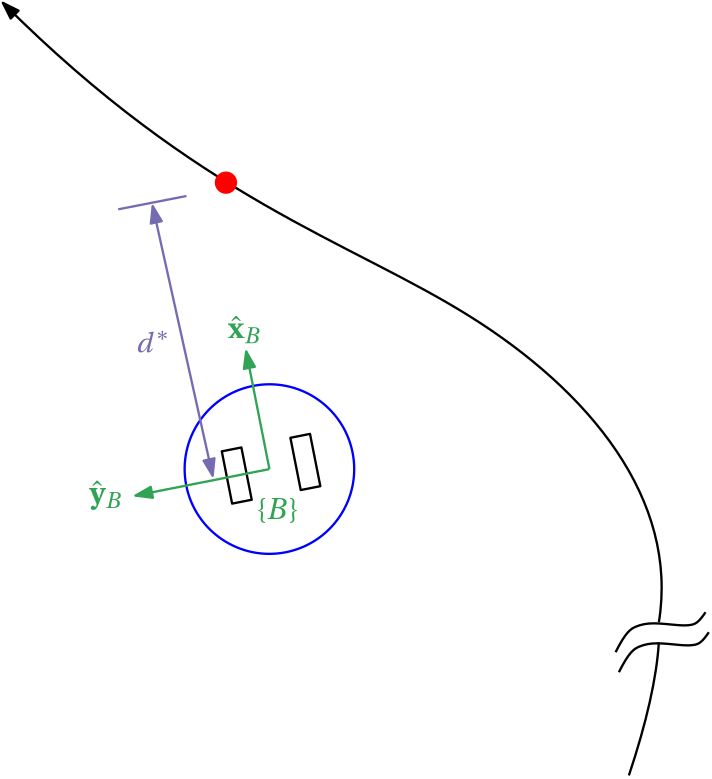

**Figure 8.8:** Robotic platform tracking a moving point using velocity control (pure pursuit).
 

The aim of the controller is to force $e_d \rightarrow 0$ , which implies that $\sqrt{{^We_x^2}+{^We_y^2}} = d^\ast$. That is, the Euclidean distance from the robot to the pursuit point equals $d^\ast$ when the tracking error goes to zero. Note that the constant offset while the robot is in motion implies that we are no longer controlling the position of our robot directly, but rather controlling the robot's velocity. To accommodate this change, we restructure our velocity controller as follows:


$$\begin{array}{cc}v^* = k_{v_1} e_d + k_{v_2} \int e_d dt,\end{array}$$


which denotes a proportional-plus-integral (PI) controller form with controller gains $k_{v_1}>0$ and $k_{v_2}>0$ . The integral term is required to provide a nonzero velocity command when the corresponding error, $e_d$ is zero. The orientation controller remains unchanged and is repeated below for sake of convenience:


$$\begin{array}{cc}\dot\psi = k_\psi\left( \psi^\ast-\psi \right) = k_\psi \left( \tan^{-1}\frac{{^We_y}}{{^We_x}}-\psi \right),\end{array}$$


where $k_\psi>0$ . The orientation controller fulfills a similar role as in the previous scenario, but depending on the variability in the specific trajectory, more control action will be required to continuously readjust the robot in order to face the pursuit point.

While the kinematic model of the wheeled robot is nonlinear in nature, we can model the incremental position behaviour in $\{B\}$ using the loop transfer function of


$$P_v(s)=\frac{\Delta p(s)}{^Be_x(s)}=\frac{{k_v}_1s+{k_v}_2}{s^2},$$


with the input to this system being translation error term ${^Be_x}$, and the output being the incremental position change in $\{B\}$. Recalling [Control Systems](https://in.mathworks.com/matlabcentral/fileexchange/160301-control-systems-university-of-cape-town), the closed-loop behaviour follows as


$$\begin{array}{ll}
T_v(s)
&=&\frac{{k_v}_1s+{k_v}_2}{s^2+{k_v}_1s+{k_v}_2},\\
\end{array}$$


which implies that the close-loop system is second order with two poles and one zero. The zero is located at $z=-\frac{{k_v}_2}{{k_v}_1}}$, and the poles are located at


$$p =-\frac{{k_v}_1}{2}\pm \frac{\sqrt{{k_v}_1^2-4{k_v}_2}}{2}.$$


syms kv1 kv2 positive
syms s
solve(s^2+kv1*s+kv2==0,s)

$$ans = \left(\begin{array}{c} -\frac{{\mathrm{kv}}_{1}}{2}-\frac{\sqrt{{{\mathrm{kv}}_{1}}^{2}-4\,{\mathrm{kv}}_{2}}}{2}\\ \frac{\sqrt{{{\mathrm{kv}}_{1}}^{2}-4\,{\mathrm{kv}}_{2}}}{2}-\frac{{\mathrm{kv}}_{1}}{2} \end{array}\right)$$

The design of the PI controller can be accomplished using trial and error (not ideal) or using a model-based loop shaping approach, for example as detailed in [Control Systems](https://in.mathworks.com/matlabcentral/fileexchange/160301-control-systems-university-of-cape-town).

#### Example: Pure pursuit controller

Play around with the simulation parameters below to see how they affect the overall performance. Some important parameters are:

- `d_star `- the look-ahead distance, which will affect the smoothness of the trajectory.

- `k_v1`, `k_v2`, and `k_psi `- affect the maneuverability of the robot and must be selected appropriately in terms of settling time requirements.

- The initial robot pose, `robotPose `- depending on how displaced the robot initially is from the path will affect its long-term tracking ability.

d = 1; %m
r = 0.5; %m
robot = differentialDriveKinematics( TrackWidth=d, WheelRadius=r)

robot =   differentialDriveKinematics with properties:

      VehicleInputs: 'WheelSpeeds'
         TrackWidth: 1
        WheelRadius: 0.5000
    WheelSpeedRange: [-Inf Inf]


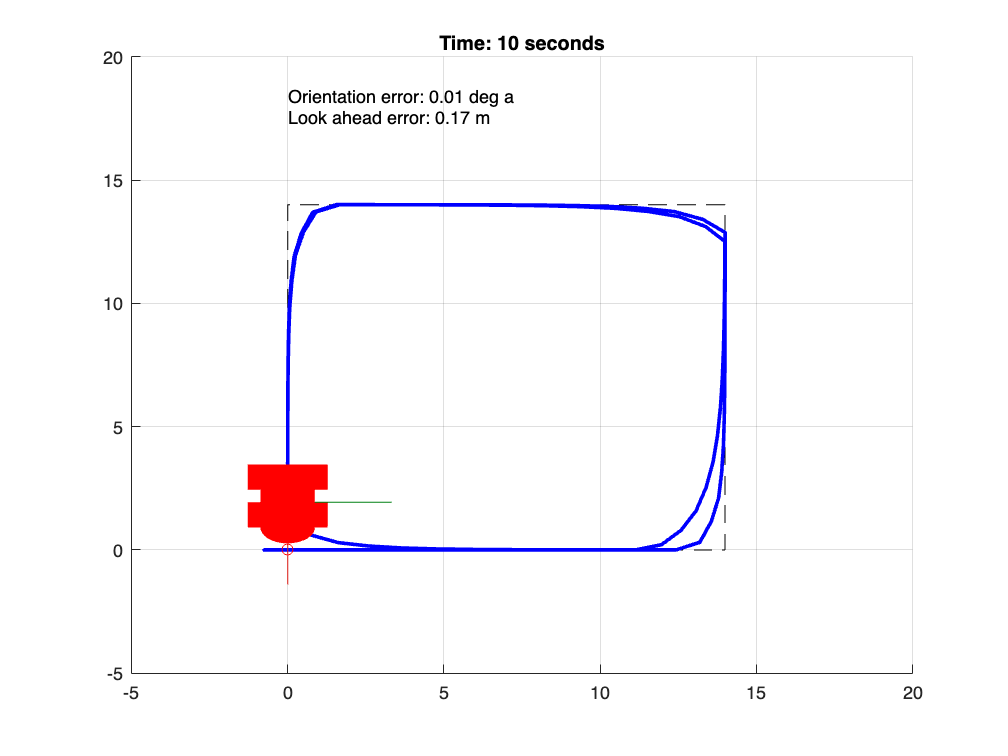


dT = 0.1;  %update/sample time
timer = rateControl(1/dT);

k_psi = 18; %orientation controller proportional gain
k_v1 = 3.6; %linear velocity proportional gain
k_v2 = 3.4; %linear velocity integral gain
d_star = 2.9;   %look ahead distance

L = 14; 
 
s1 = [linspace(0,L,1e3); zeros(1,1e3)];
s2 = [L*ones(1,1e3); linspace(0,L,1e3)];
s3 = [linspace(L,0,1e3); L*ones(1,1e3)];
s4 = [zeros(1,1e3); linspace(L,0,1e3)];
S = [s1 s2 s3 s4];

robotPose = [0 0 0]';
ev_int = 0;
t = 0;
psi_des_past = 0;
pTrail = [];
noOfLoops = 2;

S_ = [];
for i=1:noOfLoops
    S_ = [S_ S];
end

for i=1:(5*noOfLoops/dT)  %run the simulation for a time equivalent to 3 seconds
    figure(1),clf,hold on
    plot(S(1,:),S(2,:),'k--')

    p_des = S_(:,length(S_)/(5*noOfLoops/dT)*i);
    e_p_wf = p_des(1:2)-robotPose(1:2);

    %orientation control
    psi = robotPose(3);
    psi_des = atan2(e_p_wf(2),e_p_wf(1));
    
    e_psi = psi_des-psi;
    if( abs(e_psi)>pi )
        e_psi = -sign(e_psi)*( 2*pi-abs(e_psi) );
    end
    u_psi = k_psi*e_psi;
    %position control
    ev = norm(e_p_wf)-d_star;
    ev_int = ev_int+dT*ev;
    u_v = k_v1*ev+k_v2*ev_int;

    phi_des = [1/r -d/(2*r);1/r d/(2*r)] *[u_v,u_psi]';
    phiL = phi_des(1);
    phiR = phi_des(2);

    robotVelocity = derivative( robot,robotPose, [phiL,phiR] );
    robotPose = robotPose + dT*robotVelocity;
    if( abs(robotPose(3))>2*pi)
        robotPose(3) = robotPose(3)-sign(robotPose(3))*2*pi;
    end

    pTrail = [pTrail robotPose(1:2)];
    plot(pTrail(1,:),pTrail(2,:),'b-',lineWidth=2)

    plotTrVec = [robotPose(1:2); 0];    %extract 2D position of robot
    plotRot = [cos(robotPose(3)/2) 0 0 sin(robotPose(3)/2)]; %quaternion that encodes 1D orientation

    axis([-5 20 -5 20]),grid on
    plotTransforms(plotTrVec', plotRot, "MeshFilePath", "groundvehicle.stl", "Parent", gca, "View","2D", "FrameSize", robot.TrackWidth/.3);

    plot(p_des(1),p_des(2),'ro')

    t = t+dT;
    title(['Time: ',num2str( t ), ' seconds'])
    text(0,18,{['Orientation error: ',num2str( e_psi*180/pi,'%.2f' ), ' deg a'], ...
                 ['Look ahead error: ',num2str( norm(e_p_wf)-d_star,'%.2f' ), ' m']})

    drawnow
    waitfor(timer);
end